%varying d (dimensions in PCA)
load('pose.mat');

%Restructuring data:

[p1,p2,poses,subjects]=size(pose)

p1 = 48

p2 = 40

poses = 13

subjects = 68


Ks = 5:5:100; 
Kacc = zeros(size(Ks,2),2); %tracking accuracy wrt k (kNN (k=20,L1),kNN(k=20,L2))


k = 68;

counter = 1;
%for d = ds
d = 5 

d = 5


    pose_trainX = zeros(10*k,p1*p2);
    pose_trainY = zeros(10*k,1);
    pose_testX = zeros(3*k,p1*p2);
    pose_testY = zeros(3*k,1);
    
    for i = 1:k
        for j = 1:10
            temp = pose(:,:,j,i);
            idx = (i-1)*10+j;
            pose_trainX(idx,:) = temp(:); 
            pose_trainY(idx)=i;
        end
        
        for j = 11:13
            temp = pose(:,:,j,i);
            idx = (i-1)*3+(j-10);
            pose_testX(idx,:) = temp(:); 
            pose_testY(idx)=i;
        end
        
    end
    %now pose: rows = image, cols = pixel data
    
    
    
    
    %[pose_trainX2,V,mu_trainP] = myPCA(pose_trainX,d);
    
    %calibrating PCA using training data:
    train_nP = size(pose_trainX,1);
    mu_trainP = mean(pose_trainX,1);
    pose_trainX_center = pose_trainX-repmat(mu_trainP,[train_nP,1]);
    [U,S,V] = svd(pose_trainX_center);
    
    %applying PCA to training data
    pose_trainX2 = pose_trainX_center*V(:,1:d);
    
    %applying PCA to test data
    test_nP = size(pose_testX,1);
    pose_testX2 = (pose_testX-repmat(mu_trainP,[test_nP,1]))*V(:,1:d); 
    
    
for K = Ks    
    %kNN
    
  %  K = 20;
    l=1;
    pose_testY_prK = myKNN(pose_trainX2,pose_trainY,pose_testX2,K,l);
    
    pose_Kcorrect = (pose_testY_prK==pose_testY);
    Kacc(counter,1) = mean(pose_Kcorrect);
    
%    K = 20;
    l=2;
    pose_testY_prK = myKNN(pose_trainX2,pose_trainY,pose_testX2,K,l);
    
    pose_Kcorrect = (pose_testY_prK==pose_testY);
    Kacc(counter,2) = mean(pose_Kcorrect);
   
    counter=counter+1;
end

clf("reset")

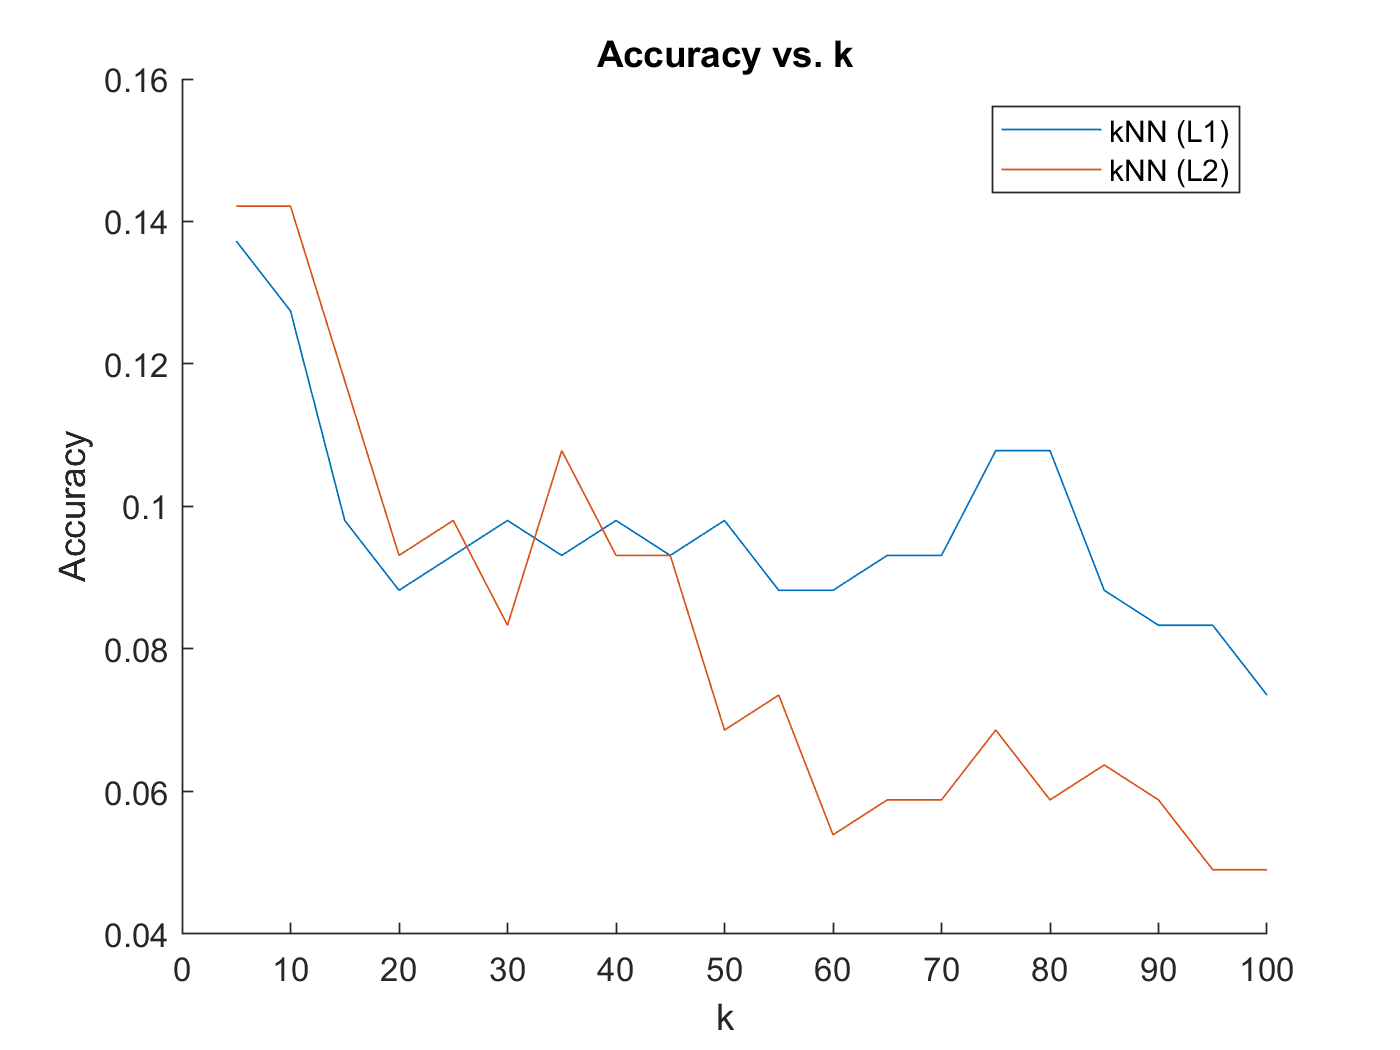

%plotting results
figure(2)
hold on
PL1 = plot(Ks,Kacc(:,1));
PL2 = plot(Ks,Kacc(:,2));
%PL3 = plot(ks,kacc(:,3));
%PL4 = plot(ks,kacc(:,4));
xlabel("k")
ylabel("Accuracy")
title("Accuracy vs. k")
legend([PL1,PL2],"kNN (L1)","kNN (L2)")
hold off